## II/ Etude du signal sinusoïdal : x(t)

#### II.1/ Récupération et affichage du signal:

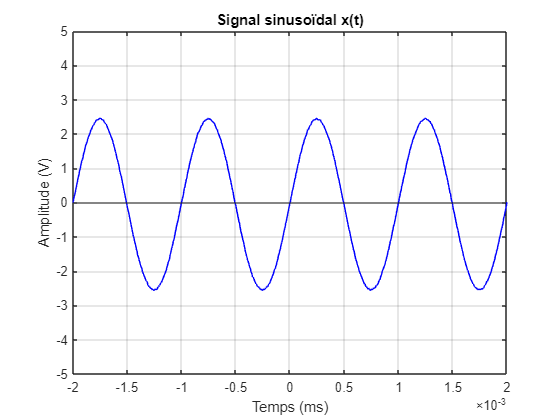

temp = transpose(Trace_1); % récupère le tableau Trace_1
t = temp(1,:);
x = temp(2,:);

Ns = size(x); 
Ns = Ns(2); %nombre d'échantillon
Te = t(2)-t(1); %période d'échantillonnage 

fe = 1/Te;

plot(t,x,"b"); %trace le signal x(t) en bleu
title("Signal sinusoïdal x(t)"); %donne un titre au graphe
ylabel("Amplitude (V)");
xlabel("Temps (ms)");
yline(0)
axis([-2e-3 2e-3 -5 5]); % règle les axes
yticks(-5:1:5); %permet de régler l'échelle verticale
xticks(-2e-3:0.5e-3:2e-3); %permet de régler l'échelle horizontale
grid on;



Amplitude = (max(x) - min(x)) % Calcul de l'amplitude

Amplitude = 5.0251

#### II.2/ Affichage du spectre du signal:

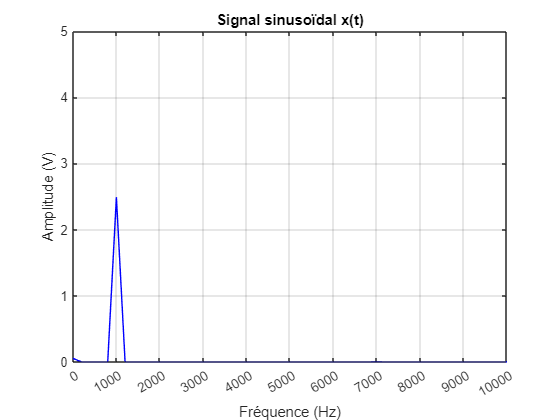

[X, F]=spectre(x,fe,Ns); %calcul du spectre

plot(F,X,"b"); %trace le spectre de x(t) en bleu
title("Signal sinusoïdal x(t)"); %donne un titre au graphe
ylabel("Amplitude (V)");
xlabel("Fréquence (Hz)");
yline(0);
axis([0 10e3 0 5]); % règle les axes
yticks(0:1:5); %permet de régler l'échelle verticale
xticks(0:1e3:10e3); %permet de régler l'échelle horizontale
grid on;


[amp, index] = max(X)

amp = 2.4897

index = 6

Ffondamentale = F(index)

Ffondamentale = 1.0000e+03

#### II.3/ Calcul du fondamentale et de Pmoy:

T = 1/Ffondamentale

T = 1.0000e-03


NSparperiode = round(T/Te)

NSparperiode = 200


Xmoy = 1/T * sum(X(1:NSparperiode-1)) * Te

Xmoy = 0.0136


Z = x.^2;

Xeff = sqrt( 1/T * sum(Z(1:NSparperiode-1) * Te ))

Xeff = 1.7610

## III/ Etude du signal carré PWM y(t):

#### III.1/ Récupération et Affichage du signal:

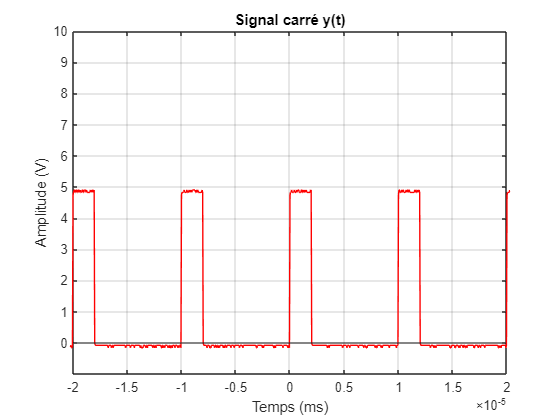

pwm = transpose(Trace_2); % récupère le tableau Trace_2
tY = pwm(1,:);
y = pwm(2,:);

NsY = size(y);
NsY = NsY(2); %nombre d'échantillon
TeY = tY(2) - tY(1); %période d'échantillonnage

feY = 1/TeY;

plot(tY,y,'r');
title("Signal carré y(t)"); %donne un titre au graphe
ylabel("Amplitude (V)");
xlabel("Temps (ms)");
yline(0)
axis([-2e-5 2e-5 -1 10]); % règle les axes
yticks(0:1:10); %permet de régler l'échelle verticale
xticks(-2e-5:0.5e-5:2e-5); %permet de régler l'échelle horizontale
grid on;

#### III.2/ Calcul des valeurs moyenne et efficace du signal:

E = max(y)

E = 4.9045


cpt = 0;
for I = 1:NsY % Calcul du rapport cyclique
    if y(I) >= E/2
        cpt = cpt + 1;
    end
end

a = cpt/NsY

a = 0.2000


Vmoy = E * a

Vmoy = 0.9809


Veff = sqrt(E^2 * a)

Veff = 2.1934

#### III.3/ Spectre du signal:

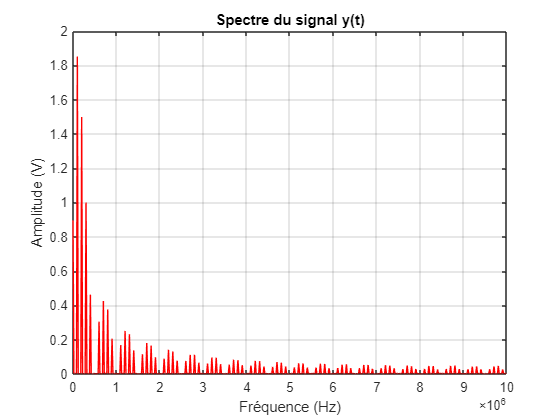

[Y, FY]=spectre(y,feY,NsY);

plot(FY,Y,"r"); %trace le spectre de x(t) en bleu
title("Spectre du signal y(t)"); %donne un titre au graphe
ylabel("Amplitude (V)");
xlabel("Fréquence (Hz)");
yline(0);
axis([0 10e6 0 2]); % règle les axes
yticks(0:0.2:2); %permet de régler l'échelle verticale
xticks(0:1e6:10e6); %permet de régler l'échelle horizontale
grid on;

#### III.4/ Définition de l'amplitude des premières raies:

% Calcul de l'amplitude de la composante continue
CC = maxk(Y(1),1)

CC = 0.8958


% Calcul de l'amplitude de la fondamentale
Aff = max(Y)

Aff = 1.8512


% Calcul de l'amplitude des Harmoniques
Yh = Y(10:end); % récupère les raies des harmoniques
H = maxk(Yh,15)

H =     1.4982    1.0001    0.4629    0.4258    0.3757    0.3050    0.2513    0.2318    0.2059    0.1810    0.1685    0.1659    0.1412    0.1378    0.1317    0.1151    0.1123    0.1119    0.0977    0.0960    0.0949    0.0894    0.0835    0.0812    0.0783    0.0766    0.0764    0.0746    0.0701    0.0665    0.0657    0.0624    0.0617    0.0607    0.0600    0.0589    0.0574    0.0567    0.0545    0.0545    0.0530    0.0528    0.0519    0.0517    0.0495    0.0495    0.0494    0.0484    0.0473    0.0470



% Calcul de la valeur efficace du signal
Parseval = CC.^2 + sum(H.^2/2)

Parseval = 3.0012

Vefficace = sqrt(Parseval)

Veff = 1.7324